# Confidence intervals

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES

## Introduction

## Example 1 Probability distribution of the mean of normal random variables

Plot the empirical distribution of the mean of a) n=1, b) n=2 and c) n=20 uniform random variables.

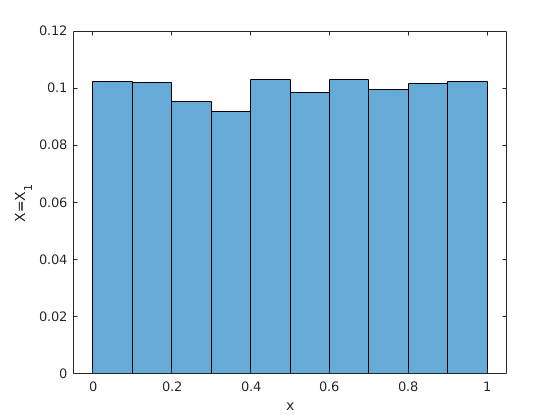

close all
clear all

% a) Plot hystogram for n=1
n1=rand(1,2000);
figure
histogram(n1, 'Normalization','probability')
ylabel('X=X_1')
xlabel('x')

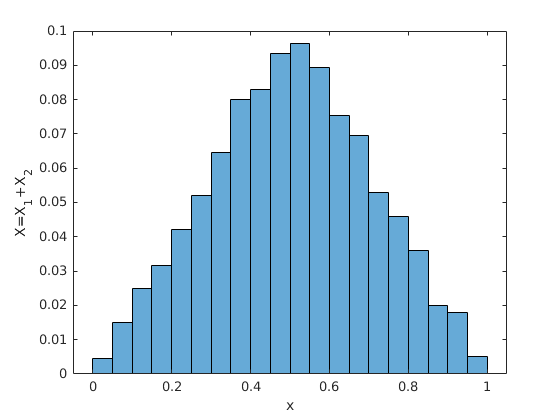


% b) Plot hystogram for n=2
n2=rand(2,2000);
m=mean(n2);
figure
histogram(m, 'Normalization','probability')
ylabel('X=X_1+X_2')
xlabel('x')

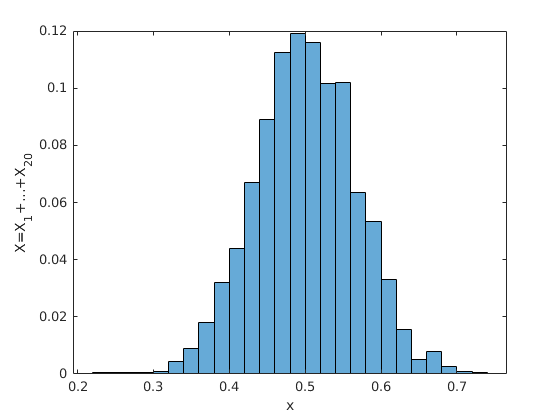


% c) Plot hystogram for n=20
n2=rand(20,2000);
m=mean(n2);
figure
histogram(m, 'Normalization','probability')
ylabel('X=X_1+...+X_{20}')
xlabel('x')


%histfit(m)

## Example 2 Plot area under normal distribution

This code is from: [https://www.mathworks.com/matlabcentral/answers/128788-need-help-plotting-confidence-intervals](https://www.mathworks.com/matlabcentral/answers/128788-need-help-plotting-confidence-intervals)

alpha = 0.05;           % significance level - change to 0.34 for 66% confidence
mu = 0;              % mean
sigma = 1;          % std
x = linspace(mu-5*sigma, mu+5*sigma, 500);

cutoff1 = norminv(alpha/2, mu, sigma);          % Lower 95% CI is p = 0.025
cutoff2 = norminv(1-alpha/2, mu, sigma);        % Upper 95% CI is p = 0.975
y = normpdf(x, mu, sigma);

xci = [linspace(mu-5*sigma, cutoff1); linspace(cutoff2, mu+5*sigma)];
yci = normpdf(xci, mu, sigma);

figure(1)
plot(x, y, '-k', 'LineWidth', 1.5)
patch(x, y, [0.9 0.9 0.9])
patch([xci(1,:) cutoff1], [yci(1,:) 0], [1 1 1])
patch([cutoff2 xci(2,:)], [0 yci(2,:)], [1 1 1])
xticklabels({})
text(-2.5,-0.02,{' \mu-2\sigma'})
text(-0.5,-0.02,{' \mu=0'})
text(1.5,-0.02,{' \mu+2\sigma'})
message = sprintf('95 %% of the area \n under the curve');
text(-1.5,0.1,message)
title('PDF of a normal distribution N(0,1)')

## Example 3 Computing confidence intervals using Student t distribution

Generate a random sample of size 50 drawn from a normal population with mean 2V and standard deviation 0.5V.  Compute confidence intervals at 95% confidence. This solution is from Mathworks example at https://www.mathworks.com/help/stats/tinv.html.

mu = 2;
sigma = 0.5;
n = 50;

x = normrnd(mu,sigma,n,1);

Compute the sample mean, standard error, and degrees of freedom.

xbar = mean(x);
se = std(x)/sqrt(n);
nu = n - 1;

Find the upper and lower confidence bounds for the `95%` confidence interval.

conf = 0.95;
alpha = 1 - conf;
pLo = alpha/2;
pUp = 1 - alpha/2;

Compute the critical values for the confidence bounds.

crit = tinv([pLo pUp], nu);

Determine the confidence interval for the population mean.

ci = xbar + crit*se

ci =     1.8402    2.0656


Uncertainty at 95% confidence is:

U_95=(ci(2)-xbar)/2

U_95 = 0.0563

If we replace the t-ditribution with the normal distribution at 95% confidence, we will obtain similar results:

k=2;
ci_normal = [xbar - k*se, xbar + k*se]

ci_normal =     1.8408    2.0651


Uncertainty at 95% confidence is:

U_95_normal=(ci_normal(2)-xbar)/2

U_95_normal = 0.0561

## Exersizes

Excersize 1: repeat the analysis for Example 3 and comment on the difference in confidence intervals when a) n=5, n=15, n=200. Replace k=2 with k=1.96.

Excersize 2: repeat the analysis for Example 3 but compute confidence intervals at 99 % confidence.